clear;
params.modelFn = 'flat.stl';
params.prjector.kMat=[2 0 0; 0 2.666 0 ; 0 0 1];
params.prjector.rMat=eye(3);
params.prjector.res=[16 16];
params.sensor.tMat=zeros(3,1);
params.verbose = 1;
params.system_dt = 0.001;
params.scenario.dt=1;%nsec

tw=20;
tw1=ones(1,20);
tw0=zeros(1,20);
%ambient
params.scenario.data{1}.pat=zeros([params.prjector.res 1])>.5;
params.scenario.data{1}.txmod = [0 tw0 0];
params.scenario.data{1}.rxmod = [0 tw1 0];

%albedo
  P=rand([params.prjector.res 128])>.5;
%  P = reshape(eye(256),16,16,[])>0;
params.scenario.data{2}.pat=P;
params.scenario.data{2}.txmod = [0 tw1 tw1 0 ];
params.scenario.data{2}.rxmod = [0 tw0 tw1 0 ];

%depth
params.scenario.data{3}.pat=P;
params.scenario.data{3}.txmod = [0 tw1 0];
params.scenario.data{3}.rxmod = [0 tw1 0];

## run sim

[mes,gt]=runSim(params);

Generating measurment (1,1)/(1,3)
Generating measurment (1,2)/(128,3)
Generating measurment (2,2)/(128,3)
Generating measurment (3,2)/(128,3)
Generating measurment (4,2)/(128,3)
Generating measurment (5,2)/(128,3)
Generating measurment (6,2)/(128,3)
Generating measurment (7,2)/(128,3)
Generating measurment (8,2)/(128,3)
Generating measurment (9,2)/(128,3)
Generating measurment (10,2)/(128,3)
Generating measurment (11,2)/(128,3)
Generating measurment (12,2)/(128,3)
Generating measurment (13,2)/(128,3)
Generating measurment (14,2)/(128,3)
Generating measurment (15,2)/(128,3)
Generating measurment (16,2)/(128,3)
Generating measurment (17,2)/(128,3)
Generating measurment (18,2)/(128,3)
Generating measurment (19,2)/(128,3)
Generating measurment (20,2)/(128,3)
Generating measurment (21,2)/(128,3)
Generating measurment (22,2)/(128,3)
Generating measurment (23,2)/(128,3)
Generating measurment (24,2)/(128,3)
Generating measurment (25,2)/(128,3)
Generating measurment (26,2)/(128,3)
Generating me

## reconstruct

p=1;
o = genDict(params.prjector.res);

w = 16

% gamma (ambient)
collectionT = nnz(params.scenario.data{1}.rxmod)*params.scenario.dt;
g = mes{1}/collectionT;
% intensity
collectionT = nnz(params.scenario.data{2}.rxmod)*params.scenario.dt;
matB=(mes{2}-g*collectionT)/(collectionT*p);
matA  = double(reshape(params.scenario.data{2}.pat,prod(params.prjector.res),[])');
a_hat=admm(matB,o,matA,1e-5,0,1e-3,1,false);

iter	    r norm	   eps pri	    s norm	  eps dual	 objective    cond %
  1	    0.2142	    0.0041	    0.0038	    0.0016	      0.00      0.00
  2	    0.0252	    0.0041	    0.0003	    0.0016	      0.00      0.00
  3	    0.0241	    0.0041	    0.0001	    0.0016	      0.00      0.00
  4	    0.0285	    0.0041	    0.0001	    0.0016	      0.00      0.00
  5	    0.0266	    0.0041	    0.0001	    0.0016	      0.00      0.00
  6	    0.0217	    0.0041	    0.0001	    0.0016	      0.00      0.00
  7	    0.0201	    0.0041	    0.0001	    0.0016	      0.00      0.00
  8	    0.0186	    0.0041	    0.0001	    0.0016	      0.00      0.00
  9	    0.0195	    0.0041	    0.0001	    0.0016	      0.00      0.00
 10	    0.0175	    0.0041	    0.0001	    0.0016	      0.00      0.00
 11	    0.0148	    0.0042	    0.0001	    0.0016	      0.00      0.00
 12	    0.0142	    0.0042	    0.0001	    0.0016	      0.00      0.00
 13	    0.0152	    0.0042	    0.0001	    0.0016	      0.00      0.00
 14	    0.0156	    0.0042	    0.0

a_hat = reshape(a_hat,params.prjector.res);
%% depth
collectionT = nnz(params.scenario.data{3}.rxmod)*params.scenario.dt;

matB = (mes{2}-mes{3})/p;
pat_ = params.scenario.data{3}.pat.*a_hat;
matA = double(reshape(pat_,prod(params.prjector.res),[])');
rtd_hat=admm(matB,o,matA,1e-3,0,1e-1,1,false);

iter	    r norm	   eps pri	    s norm	  eps dual	 objective    cond %
  1	    0.2131	    0.0037	    0.2000	    0.0016	      0.04      0.00
  2	    0.0246	    0.0038	    0.0279	    0.0016	      0.04      0.00
  3	    0.0156	    0.0038	    0.0102	    0.0016	      0.04      0.00
  4	    0.0177	    0.0038	    0.0091	    0.0016	      0.04      0.00
  5	    0.0163	    0.0038	    0.0087	    0.0016	      0.04      0.00
  6	    0.0153	    0.0038	    0.0083	    0.0016	      0.04      0.00
  7	    0.0161	    0.0038	    0.0077	    0.0016	      0.04      0.00
  8	    0.0179	    0.0038	    0.0072	    0.0016	      0.04      0.00
  9	    0.0174	    0.0038	    0.0068	    0.0016	      0.04      0.00
 10	    0.0144	    0.0038	    0.0066	    0.0016	      0.04      0.00
 11	    0.0116	    0.0038	    0.0063	    0.0016	      0.04      0.00
 12	    0.0105	    0.0038	    0.0061	    0.0016	      0.04      0.00
 13	    0.0103	    0.0038	    0.0059	    0.0016	      0.04      0.00
 14	    0.0106	    0.0038	    0.0

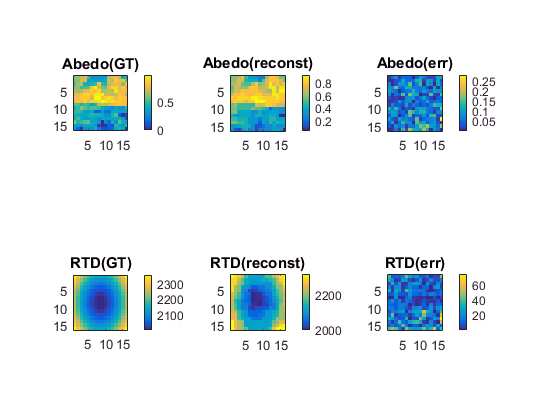

rtd_hat = reshape(rtd_hat,params.prjector.res);


%Display results
C = 299.702547; %air,mm/nsec
subplot(2,3,1);
imagesc(gt.a);title('Abedo(GT)');colorbar;axis image
subplot(2,3,2);
imagesc(a_hat);title('Abedo(reconst)');colorbar;axis image
subplot(2,3,3);
imagesc(abs(gt.a-a_hat));title('Abedo(err)');colorbar;axis image
subplot(2,3,4);
imagesc(gt.rtdS);title('RTD(GT)');colorbar;axis image
subplot(2,3,5);
imagesc(rtd_hat*C);title('RTD(reconst)');colorbar;axis image
subplot(2,3,6);
imagesc(abs(gt.rtdS-rtd_hat*C));title('RTD(err)');colorbar;axis image

% 
% [h,w,n]=size(params.prjector.pat);
% 
% 
% 
% 
% 
% 
% 
% imagesc([normByMax(z) normByMax(gt.a)])